# Tracking cantilever beam motion by tracking the edge

vid = VideoReader("VID6.mp4","CurrentTime",2.5);

%frame = readFrame(vid);
%frame = frame(500:580,1000:1010);


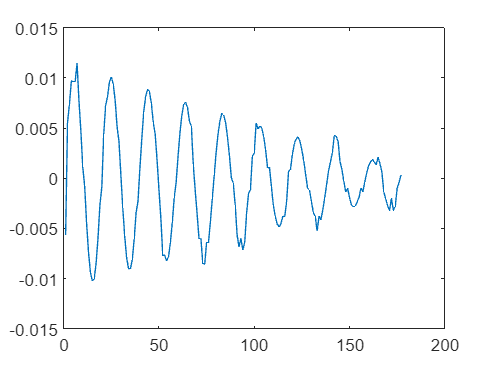

res = 3.716e-4;
disp = [];
while vid.CurrentTime < 5.5
frame = readFrame(vid);
frame = frame(500:580,1000:1010,:);
frame = rgb2gray(frame);
frameEdge = edge(frame,'canny',[0.2 0.7],4);
idx = find(frameEdge);
idx = mod((idx-1),81);
%idx = idx(idx(:,1)>10);
x = mean(idx);
x = x*res + res/2;
disp = [disp,x];
%imshowpair(frame,frameEdge,'montage');
%pause(0.1);
end
offset = mean(disp);
disp = disp - offset;
plot(disp);